# **Implementation of Arithmetic Encoding and Decoding**

###         A) Arithmetic Encoder

###         B) Arithmetic Decoder

### **A) Designing Arithmetic Encoder.**

- **In order to design a Arithmetic code for an the given character set, the probability of each character in the language is needed.**

- **Probabilities are obtained using the following table**

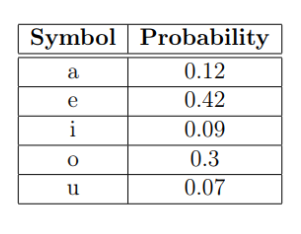

- **Functions used for this task are:**

- **Find_Ranger: ***This function is a helper function to be used in ****Arithmetic_Encoder*** *and takes the charcters along with their probabilities and finds L and H.*

- **Arithmetic_Encoder: ***This function finds the encoded signal based on the block of bits to be contained within the range of L and H.*

clear;
close all;
clc;

% Define Symbols and their Propabilities. Calculate the entropy.
symbols_Arr = ['u', 'o', 'i', 'e', 'a'];
probability_Arr = [0.07, 0.3, 0.09, 0.42, 0.12];

% Calculating the Entropy
entropy = 0;
for i = 1:length(probability_Arr)
    entropy = entropy - probability_Arr(i)*log2(probability_Arr(i));
end

fprintf("The entropy of the message is %f \n", entropy );

The entropy of the message is 1.995012 


fprintf("The sum of probabilities is %f \n ",sum(probability_Arr) );

The sum of probabilities is 1.000000 
 




%% 2. Arithmetic Encoding
code_word = ['iou'];
Encoded_Message = Arithmetic_Encoder(code_word, symbols_Arr, probability_Arr);



% Printing the Code for each Character
fprintf("=======Encoded Sequence=======")

=======Encoded Sequence=======

fprintf("Code: %s \n", Encoded_Message );

Code: 0110000010 


### **B) Designing Arithmetic Decoder.**

- **In this part, given an encoded sequence and the length of the sequence, we need to obtain the original message.**

- **Firstly, the binary bits are converted into decimal fraction value.**

- **We iterated n iterations, where n is the length of the sequence, over the symbols to know the exact multiplication of symbols that gives the fraction value.**


% 3. Arithmetic Decoding
encoded_seq = ['011000001'];
seq_len = 3;

Decoded_Message = Arithmetic_Decoder(encoded_seq, seq_len, symbols_Arr, probability_Arr);



fprintf("=======Decoded Sequence=======")

=======Decoded Sequence=======

fprintf("Message: %s \n", Decoded_Message );

Message: iou 
